
Local minimum possible.

lsqnonlin stopped because the final change in the sum of squares relative to 
its initial value is less than the default value of the function tolerance.

<stopping criteria details>



x = 1.2645


Local minimum possible.

lsqnonlin stopped because the final change in the sum of squares relative to 
its initial value is less than the default value of the function tolerance.

<stopping criteria details>



x =     1.2645    1.2645



Local minimum possible.

lsqnonlin stopped because the final change in the sum of squares relative to 
its initial value is less than the default value of the function tolerance.

<stopping criteria details>



x =     1.2645    1.2645    1.2645



Local minimum possible.

lsqnonlin stopped because the final change in the sum of squares relative to 
its initial value is less than the default value of the function tolerance.

<stopping criteria details>



x =     1.2645    1.2645    1.2645    1.2645



Local minimum possible.

lsqnonlin stopped because the final change in the sum of squares relative to 
its initial value is less than the default value of the function tolerance.

<stopping criteria details>



x =     1.2645    1.2645    1.2645    1.2645    1.2645


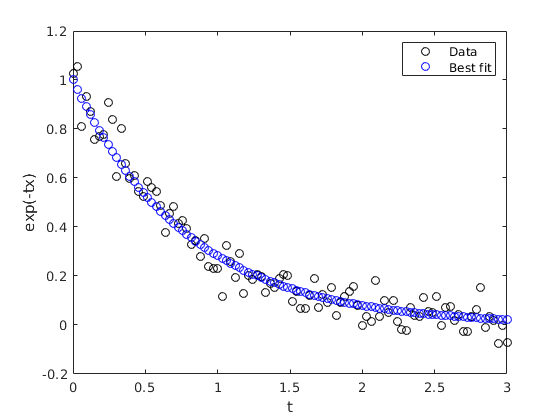

rng default % for reproducibility
d = linspace(0,3);
y = exp(-1.3*d) + 0.05*randn(size(d));


jj=[0.0001; 0.020; 0.034; 0.045; 0.77; 0.20; 0.15];
mm=[0.01; 0.1; 1; 10;  100;1000; 10000];
%
% semilogx(mm, jj.*mm, 'b')
% xlim([1,1000])

x0 = [10;20;30;40;50];

    for i = 1:5
    
    fun = @(r) (exp(-d*r)-y);
    x(i) = lsqnonlin(fun,x0(i))
    
    
    
    plot(d,y,'ko',d,exp(-x(i)*d),'bo')
    legend('Data','Best fit')
    xlabel('t')
    ylabel('exp(-tx)')
    
end